filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/Traffic Signs/Train";
imdsSigns = imageDatastore(filename, "IncludeSubfolders",true, "LabelSource","foldernames");
filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/Traffic Signs/Test";
imdsTest = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource","foldernames");

[imdsTrain, imdsVal] = splitEachLabel(imdsSigns, 0.8, "randomized");

net18 = resnet18;

augTrain = augmentedImageDatastore(net18.Layers(1).InputSize, imdsTrain);
augVal = augmentedImageDatastore(net18.Layers(1).InputSize, imdsVal);
augTest = augmentedImageDatastore(net18.Layers(1).InputSize, imdsTest);

opts = trainingOptions("adam", "Shuffle", "every-epoch", "Plots","training-progress", "ValidationData",augVal, "ValidationFrequency", 3, "MaxEpochs", 6, "OutputNetwork","best-validation");

lgraph = layerGraph(net18);

fclayer = lgraph.Layers(end-2);
lgraph = replaceLayer(lgraph, fclayer.Name, fullyConnectedLayer(9, 'Name', "NewFC"));
classlayer = lgraph.Layers(end);
lgraph = replaceLayer(lgraph, classlayer.Name, classificationLayer('Name', 'NewClass'));


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |        7.81% |       33.33% |       3.8893 |       2.8388 |          0.0010 |
|       1 |           3 |       00:00:21 |       37.50% |       57.22% |       2.6386 |       1.4362 |          0.0010 |
|       2 |           6 |       00:00:38 |       86.72% |       81.67% |       0.5192 |       0.7101 |          0.0010 |
|       2 |           9 |       00:00:55 |       97.66% |       91.67% |       0.1589 |   

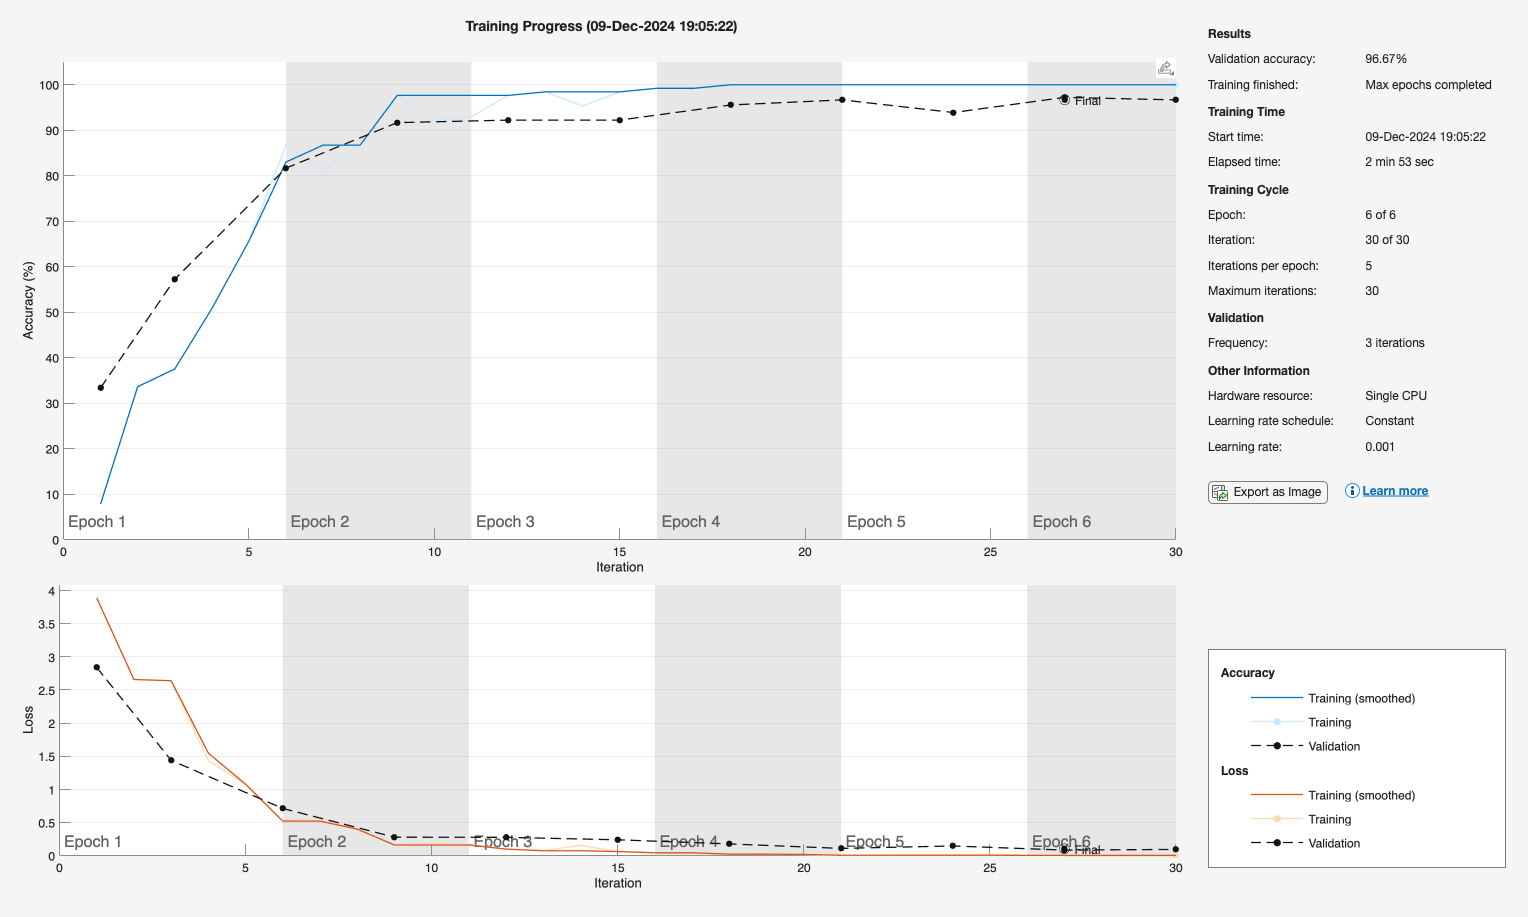

net = trainNetwork(augTrain, lgraph, opts);

preds = classify(net, augTest);

accuracy = nnz(preds == imdsTest.Labels)/length(preds)

accuracy = 0.9618

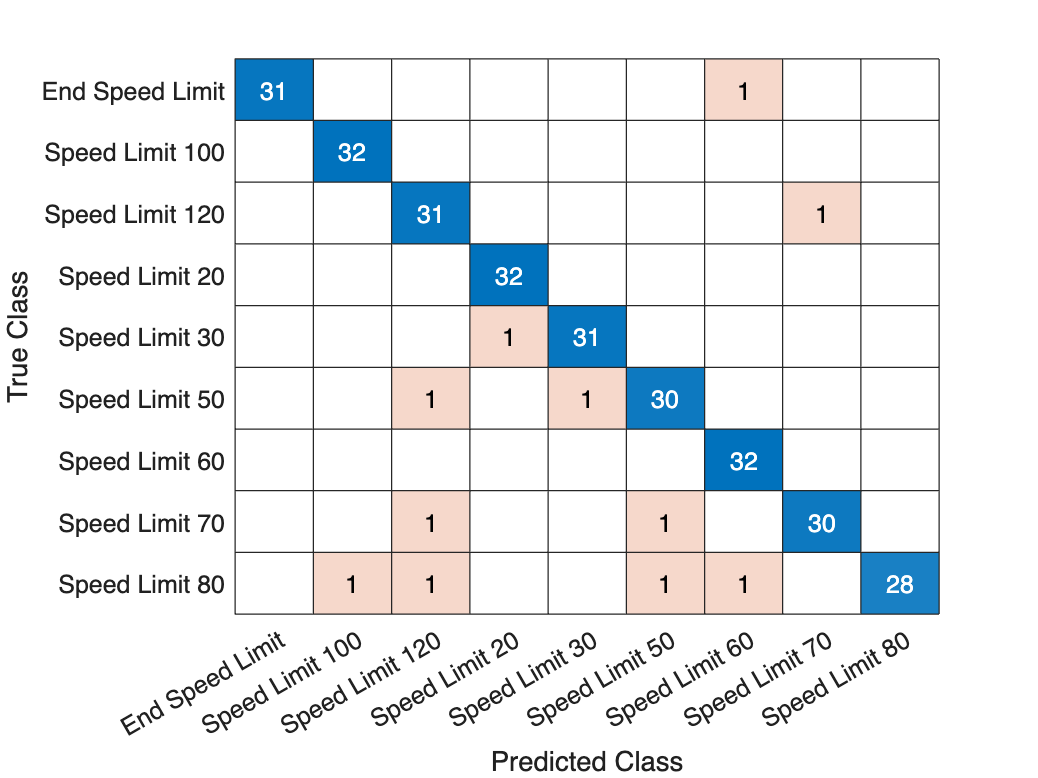

confusionchart(imdsTest.Labels, preds)